## Lab #3: Asking a statistical question

## Megan Miyasaki 

Partner: Kuan Lee

This week we are going to concentrate on asking a statistical question. This process always consists of two steps:

- Writing down in words *very precisely* what question you are trying to ask.

- Converting the precise english question into a mathematical expression. This often includes determining the pdf of the background (possibly including trials), and the to integral to do to obtain a probability.

So in this lab we will assume that we know the form of the signal-free background distribution (determining a distribution from data will be next week's lab). In each of our three examples, your task will be to state the statistical question, convert it to math, then perform the associated analyses.

## Problem 1

In our first example we are looking at the temperature reading (meta-data) associated with an experiment. For the experiment to work reliably, the temperature should be at around 12 Kelvin, and if we look at the data it is mostly consistent with 12 Kelvin to within the 0.4 degree precision of the thermometry and the thermal control system (standard deviation). However, there are times when the thermal control system misbehaved and the temperature was not near 12 K, and in addition there are various glitches in the thermometry that give anomalously high and low readings (the reading does not match the real temperature). We definitely want to identify and throw out all the data when the thermal control system was not working (and the temperature was truly off from nominal). While it is possible to have an error in the thermometry such that the true temperature was fine, and we just had a wonky reading, in an abundance of caution we want to throw those values out too.

To make this a bit concrete, we will simulate a little data. Start by simulating 100k 'good' data points assuming Gaussian fluctations, and because we are playing god adding the following 'bad' datapoints: {10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7}

**A) So our goal is to identify bad data and throw it out.**

**Prob 1a: Start by exploring the data you have created with appropriate plots**

*Below is code simulating data, of 100k good data points of a randomlu generate guassian distribution with mu = 12 and sigma = 0.4, and a couple bad data points, along with a plot that help show what is going on in the data. *

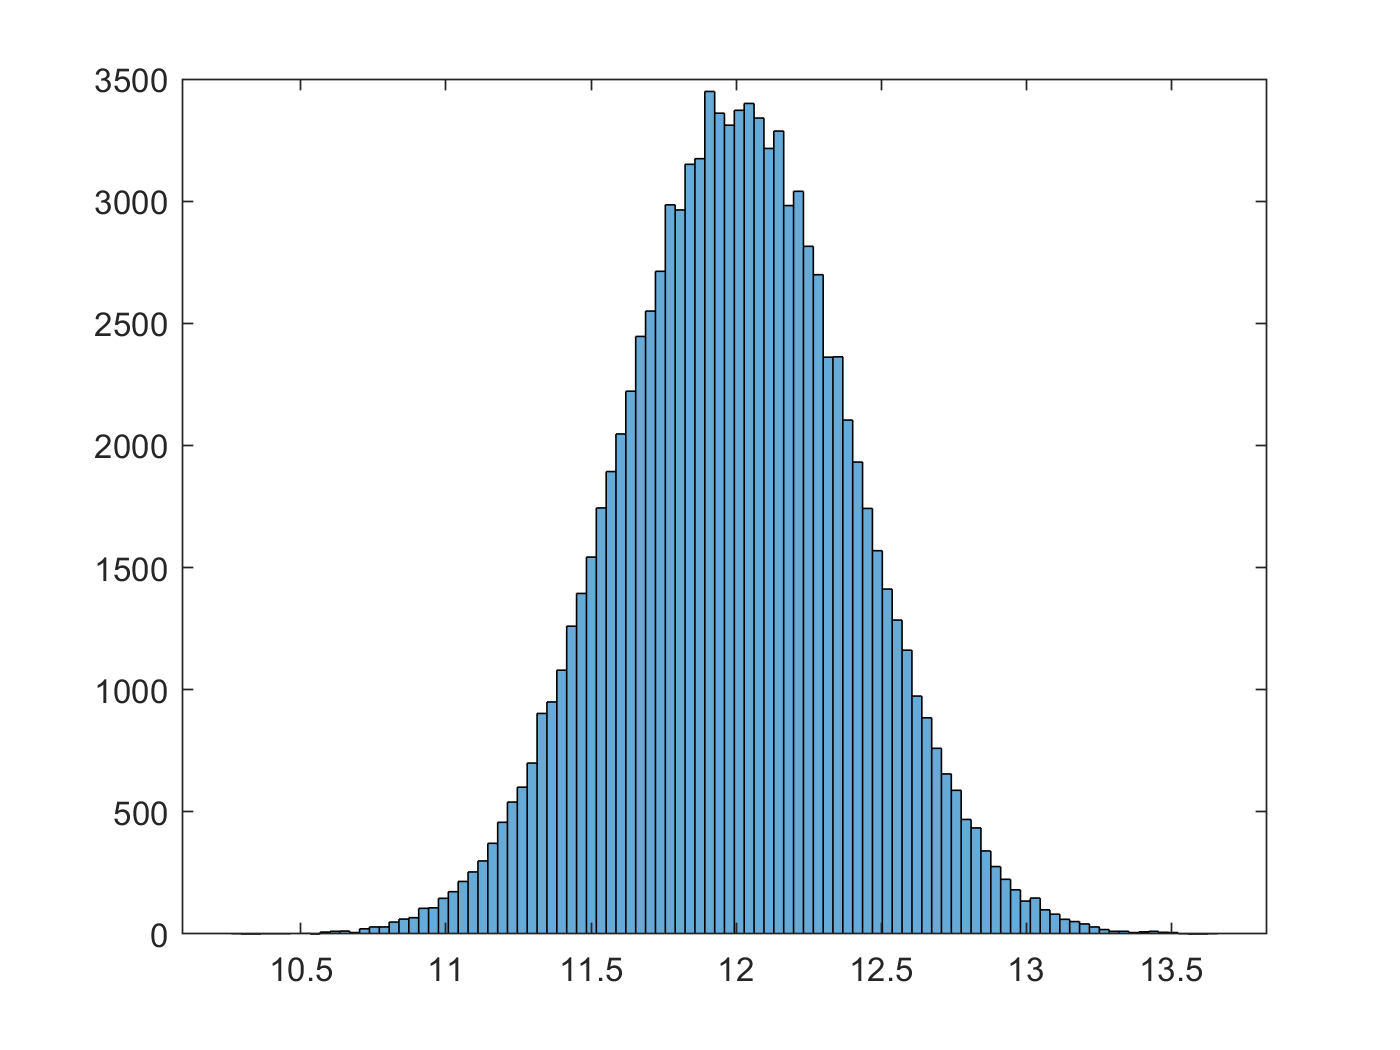

clear;close all; clc;
mu =12 ;
sigma= 0.4;

bad=[10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7]; %bad data points, for outliers not in the gauss distribution. 
good=random('Normal',mu,sigma,1,100000);


histogram(good,100)

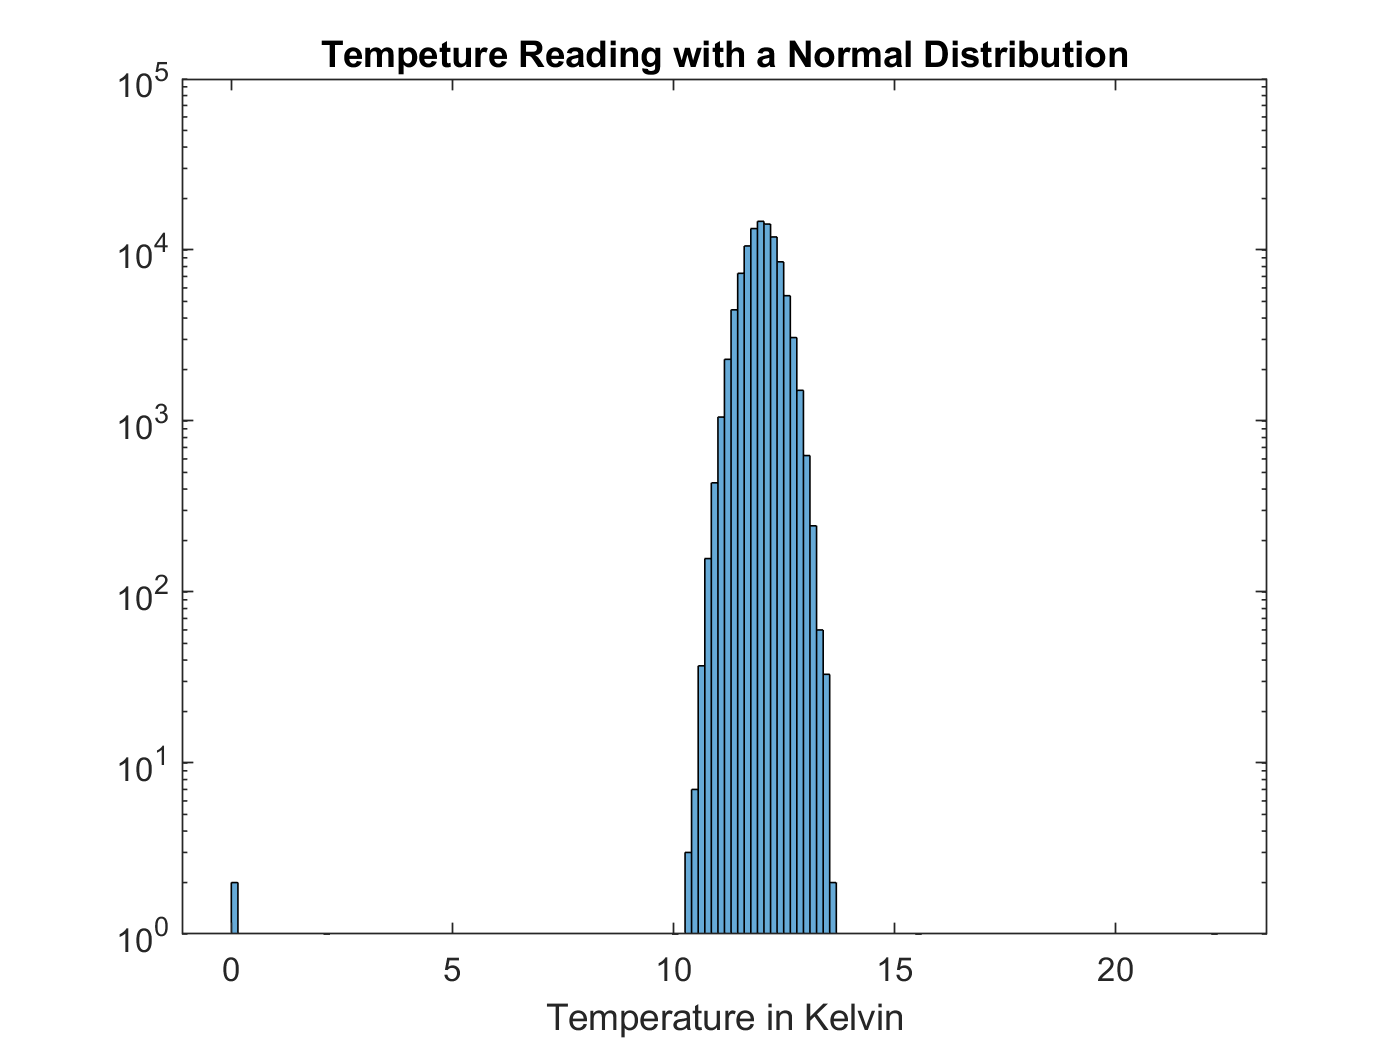


Gauss=[good bad];

histogram(Gauss,150);


set(gca,'YScale','log');
title('Tempeture Reading with a Normal Distribution')
xlabel('Temperature in Kelvin')

**Prob 2a: State the statistical question in words. Be very clear, and describe why you have chosen this statistical question.**

*When one write a statistical question, you want to include all the information one would need to understand the question as well as know what it is truly asking. One should also keep in mind that the question their asking should be able to be converted into a mathematical interpretation. Therefore this is how I interpreted my statistical question:*

If we are to expect that the Gaussian Distribution of 100,008 data points, centered around 12 Kelvin have only 8 bad data points due to a misbehavior in the thermal control system. Since we know that the probability of getting a bad data point is 8/100,008, we want to choose a sigma that would appropriately cut off the bad data points and not the good ones. What is the value 'x' of  a data point we have that is actually a bad data point (not a misbehavior in the thermal control system), allowing the discovery of a bad data point to be 3 sigma away from the mean, giving we know that there are only 8 bad points out of the only 100,008 data points in the distribuiton. 

**3 sigma was chosen after seeing the normal distribution of our 100000 points did not distribute out pass 10 and 14 which would have been the bounds of 5 sigma, seeing as we do want to get rid of bad data, we can see that 3 sigma will take off data points that we know are bad that we want to get rid of while minimizing the amount of good data points we have that we would need to toss. *

**Prob 3a: Restate your question in math. Be very clear.**

*First I want to find what 3 sigma is in an x value, so I can get clear bounds of integration, to see which data points I will toss out as "bad data points"*


$$p=F\left(x\left|\mu ,\sigma \right.\right)=\frac{1}{\sigma \sqrt{2}}\int_{-\infty }^{X\sigma } e^{\frac{-{\left(x-\mu \right)}^2 }{2\sigma^2 }} \textrm{dx}=\frac{1}{\sigma \sqrt{2}}\int_{10\ldotp 8}^{13\ldotp 2} e^{\frac{-{\left(x-\mu \right)}^2 }{2\sigma^2 }} \textrm{dx}$$


prob5sigma= 1-normcdf(3) % this is the probability of getting a bad data point of 5 sigma. 

prob5sigma = 0.0013

%Comment: Since you have changed the trheshold from 5 sigma to 3 sigma, you
%might want to rename your variable and adjust your discription.

xval=norminv(prob5sigma,12,0.4) % this is our lower bound of our integral, so our upper bound would be 14. 

xval = 10.8000

*From what we have found we can confirm that by choosing **5 sigma** (****You might want to change this to 3 sigma)****it is like taking the originally standard deviation of 0.4 and mutipling it by 3 to get 1.2. Therefore our upper bound is 13.2, and lower bound is 10.8, so anything outside these bounds, we will throw away these data points. This process of thinking does not working, for non-normal distribution because it would not have the same constant change and symmetry that our normal distributio have.  *

**Prob 4a: Apply your statistical test and construct a truth table.**

*Now that we set  any data points that have below a 10 Kelving temp or above a 14 kelvin temp is a bad data point we can continue to play god and see if we chose the right sigma. Since we know that there are only 8 bad data points, how many did we throw out that were good, and how many did we keep that were bad. Below is code finding how many good data points we threw away, and we already know how many bad ones we kept that would not have been taken off from our 3 sigma, 10.8<A<13.2*

***True Negative: all truly good data points we threw out ***

***False Postive: all truly bad data points we kept***

***True Postive: all truly good data points we kept ***

***False Negative: all truly bad data that we threw out ***

A = [good];
I = A<10.8; % all values in A less than 10.8
B=A(I); % getting the values out of logical array
I2 = A>13.2; % all values in A greater than 13.2
B2=A(I2); % getting values out of logical array
TrueNeg = length(B)+length(B2) % how many truly good values we tossed 

TrueNeg = 246

TruePos = 100000-TrueNeg % all the truly good data points we kept 

TruePos = 99754

M = [bad];
L = M<10.8; % all values in A less than 10.8
C=M(L); % getting the values out of logical array
L2 = M>13.2; % all values in A greater than 13.2
C2=M(L2); % getting the values out of logical array
FalseNeg = length(C) + length(C2);% all truly bad data points I tossed 
FalsePos = 8-FalseNeg % all truly bad data I kept in my data

FalsePos = 1

**                    True        False **

**Positive    **99723           1

**Negative     **279            7

**The idea is how often you kept the known good data (True Pos), how often you correctly discarded bad data (False Neg), and how often mistakes were made of either omission or commission (True Neg, & False Pos).**

*From the table and definitions we can see that 3 sigma is a very good use of a discovery because it reatins most of the good data and gets rid of most of the bad data. *

**B) How does the number of omissions, where you threw out good data, depend on the statistical threshold you chose and is it a predictable quantity?**

Since we know we have 100,000 good data points and only 8 bad ones, we would want to choose a statistical threshold that would retain most of the good data and throw out as little as possible. If we did not know exactly what the bad data points were and how the distribution curved, we would probably choose a high**(higher)** sigma than 3, such as 5 sigma, it would get rid of less data than 3 sigma, and maintain most of the good data points. But since we are playing god, we can use the knowledge of what the bad data points are and how the distribuiton distributes out to pick an appropriate sigma. 

**C) Are there mistakes of commission (bad data getting in)? If yes, are they avoidable and how do they depend on your statistical threshold?**

Bu**(But)** choosing 3 simga I did let one bad data point in, which was the data point related to the 12.7 Kelvin tempertuare, this in an avoidable mistake, but to do so you would have to cut out way too much data, and only accept 1 sigma of your data, because 2 sigma would still encompass that bad point. 

- *1 sigma = 0.4 --> bounds 11.6 to 12.4*

- *2 sigma = 0.8 --> bounds 11.2 to 12.8 ( the bad data point is 12.7)*

1 sigma is an undesirable statistcal tolerance because it will cut out such a significant amount of data. 

## Problem 2

In this example we will be looking for asteroids. If we look at the alignment of stars on subsequent images, they don't perfectly align due to atmospheric and instrumental effects (even ignoring proper motion). The resulting distribution is two dimensional, and for this lab let's assume it is a 2D Gaussian with 1 arcsecond RMS. Or said another way, if I histogram how far all the (stationary) stars appear to have moved I get something like:

`In [65]:`

`#a = np.concatenate(np.array(stats.norm.rvs( scale = 1, size = 100000)), np.array(stats.norm.rvs( scale = 1, size = 100000)), axis = 1)``a` `=` `np``.``vstack``((``stats``.``norm``.``rvs``(` `scale` `=` `1``,` `size` `=` `100000``),` `stats``.``norm``.``rvs``(` `scale` `=` `1``,` `size` `=` `100000``)))``a``.``shape``fig``,` `ax` `=` `plt``.``subplots``(``1``,` `1``)``ax``.``hist2d``(``a``[``0``,:],``a``[``1``,:],``bins``=``100``);``ax``.``set_aspect``(``'equal'``,` `'box'``)`

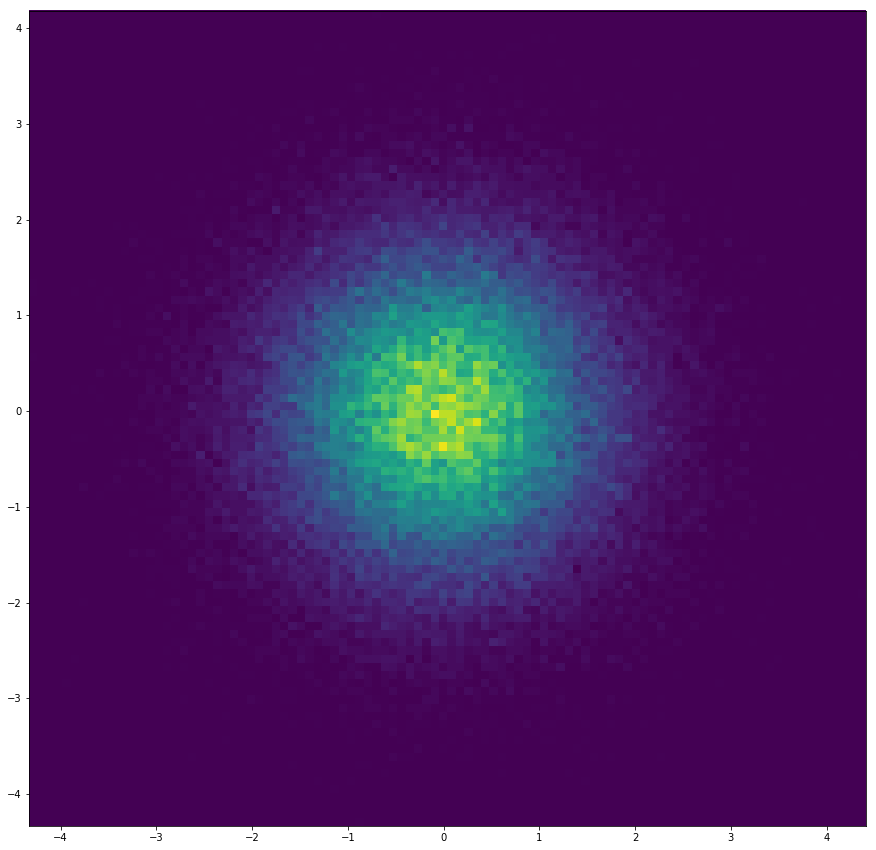

**If I have a potential asteroid, it will have some true movement between the images. We would like a '5 sigma' detection of movement. What is that distance in arcseconds?**

**Prob 1: What is the question in words?**

Given we have a 2D Gaussina Distribution with 1 arcsecond RMS, we can use a Rayleigh Distribution because they are often used to find the amplitude of a 2D Gaussin Distribution, what is the probability the movement is of a potential asteroid and not a stationary star, given a statistical threshold of detection to be 5 sigma, and what is the distance in arcseconds at that detection of movement? 

**(Maybe try: How big does an observed displacement have to be so that the probability of observing a displacement that is equal to or greater than the observed displacement from the background is smaller than 5 sigma?)**

**Prob 2: What is the question in math?**

Since we know it is a Rayleigh Distribtuion, where we have two zero mean of a guassian distribution with the same sigma, then the Rayleigh distributied is: 


$$\begin{array}{l}
\sqrt{X_1^2 +X_2^2 }\;;\mathrm{mean}=\;\Delta x\;\mathrm{arcseconds}=\Delta y\;\mathrm{arcseconds}=0\;;\;\mathrm{with}\;\mathrm{sigma}=1\;\mathrm{arcsecond}\ldotp \\
\mathrm{with}\;\mathrm{the}\;\mathrm{probability}\;\mathrm{density}\;\mathrm{function}\;\left(\mathrm{pdf}\right):f\left(x\right)=\frac{x}{\sigma^2 }\mathrm{exp}\left(\frac{{-x}^2 }{{2\sigma }^2 }\right)\;;x\;\ge ,\sigma =1\\
\mathrm{mean}=\mu =\sigma \sqrt{\frac{\pi }{2}}\\
\mathrm{variance}=\sigma^2 =\sigma^2 \left(2-\frac{\pi }{2}\right)\\
\mathrm{The}\;\mathrm{cumulative}\;\mathrm{distribution}\;\mathrm{function}\;\left(\mathrm{cdf}\right)\;\mathrm{is}:\\
F\left(x;\sigma \right)=1-e^{\frac{{-x}^2 }{{2\sigma }^2 }} \;\mathrm{for}\;\mathrm{all}\;x\in \left\lbrack \left.0,\infty \right)\right\rbrack \ldotp 
\end{array}$$


**Comment:  I don't think the sigma of Rayleigh distribution will be 1.You can look at my lab writeup and see how I find the sigma for the Rayleigh. Again, my approach may not be correct.**

**Also, can you write a matlab code to comput what is the displacement that counts as a 5 sigma detection?**

Our pdf, take the postion x, from the originally **menas(?)** of $\Delta x\;\textrm{and}\;\Delta y$ and see how far it out, compared to the 1 arcsecond for 1 sigma, if this is farther out than a 5 sigma detection, we can claim this movement to be an asteriod and not a stationary star. 

**[Hint: Come up with an analytic description of your pdf(). The Blue Book may be helpful here.]**

## Problem 3

As we discussed in class, one of the key backgrounds for gamma-ray telescopes are cosmic rays. Cosmic rays are charged particles—usually protons or electrons but can include atomic nuclei such a alpha particles (helium) or iron. Because of their charge cosmic rays spiral in the magnetic field of the galaxy. From the perspective of the Earth they appear to be coming uniformly from all directions like a high energy gas, and the direction the cosmic ray is travelling when it reaches the Earth tells us nothing about where it came from because we don't know what tortured path it has taken through the galaxy to reach us. However, at trillion electron volt energies and above, the spiral loops are fairly big and the sun and the moon will block cosmic rays. This means the sun and the moon appear as holes in the cosmic ray sky (cosmic rays from that direction are absorbed).

Assume a moon sized patch on the sky we normally have a cosmic ray rate of 1 cosmic ray per minute (arrivals are random in time). If we can observe where the moon is for 8 hours per night (not too close to the horizon) and we observe for 15 days and see 6800 cosmic rays, what is the signficance of our moon shadow detection?

**As always:**

**Prob 1: What is the question in words?**

As we observe the moon fro 8 hours per night for 15 days, and we know that the cosmic ray rate is 1 cosmic ray pery**(per)** minute, we expect our background to be 7200 cosmic rays over that time. Therefore when we observed 6800 cosmic rays instead of our expected value, what is the signicance of our moon shadow detection, or what sigma away from the mean are we away from the expected value? 

**Prob 2 Translate the question to math, describing both the expected background pdf() and the integral you need to do.**

From what we can expect, a moon size patch is 1 cosmic ray per minute, so when we observe a moon for 15 day and 8 hours per day we should get:

15(days)*8 (hours/day)*60(min/hour)

**Comment: Talk about the integral you have to evaluate to find the probability and the sigma associated with the probability. You can look at my writeup for more details.**


$$P\left(6800\right)\int_{-\infty }^{6800} 1/\sqrt{2\pi \sigma^2 }\;\exp \left(-{\left(x-\mu \right)}^2 /2\sigma^2 \right)\textrm{dx}$$



$$1-P\left(6800\right)=\int_{-\infty }^X 1/\sqrt{2\pi \sigma^2 }\;\mathrm{exp}\left(-{\left(x-\mu \right)}^2 /2\sigma^2 \right)\mathrm{dx}\;,\mu =0\;,\sigma =1\;\;$$


*Below is the code of summing over the cosmic rays that we find in the 15 days for the 8 hours a night we observe the sky. *

expectedval = 15*8*60 % expected cosmic rays one would observe. 

expectedval = 7200

x=0:100;
poisson = makedist("Poisson",'lambda',7200);
prob = pdf(poisson,x);


D= 7200; 
prev=prob;
    for j = 1:7200-1
        sums_d=conv(prev,prob);
        prev=sums_d;
    end
 %Since you talked about how the Poisson will approaches Gaussian after
 %convolving for many times, can you plot the distribution you found by
 %convolving 7200 times and the approximate Gaussian distribution in the
 %same plot to show how closely they overlap?

Due to sake of time and storage, I did not make a plot for this problem since the amount of convolution were so high, I know from previous labs that if you sum or convolute many times over the distribution will converge to a guassian distribution, therefore this discrete possion distribution can be treated as a guassian distribution for the rest of the time being. 

**Prob 3: Convert to sigma.**

*In this code I will take the probability distribution that I have found after convolving it many times over, and see how many sigmas away from the mean the observed value of 6800 cosmic rays. Now according to the central limit theorem, a  Poisson distribution Poiss(*$\lambda$*) can be approximate by a Gaussian distribution with mean = *$N\lambda$*, and *$\sigma =\sqrt{N\lambda }$*, where N is the sample size of Poisson distribution*

prob = 1 - cdf('Normal',7200,sqrt(7200), 6800);
%Comment: Since you actually want to integrate from left side of the pdf to
%6800, prob = cdf('Normal',7200,sqrt(7200), 6800). You can take the "1-"
%away.
sigma = icdf('Normal',1-prob,0,1)

sigma = 1.0463

With this calculation I have converted the sigma to 1.0463, which means that the 6800 cosmic ray detection is not significant enough to say that it is the moon's shadow. 